% Load the dataset (your file must be in the current folder)
filename = 'combined_rat_delays.csv';
tbl = readtable(filename);

% Only select trials 1-6 for each rat
nTrials = 6;
mask = tbl.trial <= nTrials;
tbl = tbl(mask, :);

% Find unique rat IDs
rats = unique(tbl.day);
nRats = numel(rats);

% Initialize matrices for data (rats x trials)
led_on = nan(nRats, nTrials);
arrival = nan(nRats, nTrials);
latency = nan(nRats, nTrials);

% Fill matrices by rat and trial
for i = 1:nRats
    for t = 1:nTrials
        idx = tbl.day == rats(i) & tbl.trial == t;
        if any(idx)
            led_on(i, t) = tbl.led_on_time_s(idx);
            arrival(i, t) = tbl.arrival_time_s(idx);
            latency(i, t) = tbl.delay_s(idx);
        end
    end
end

% Convert to tables with trial variables
led_on_tbl = array2table(led_on, 'VariableNames', {'led1','led2','led3','led4','led5','led6'});
arrival_tbl = array2table(arrival, 'VariableNames', {'arrival1','arrival2','arrival3','arrival4','arrival5','arrival6'});
latency_tbl = array2table(latency, 'VariableNames', {'latency1','latency2','latency3','latency4','latency5','latency6'});

% Write to XLSX
output_xlsx = strrep(filename, '.csv', '_6trial_results.xlsx');
writetable(led_on_tbl, output_xlsx, 'Sheet', 'led_on_time_s');
writetable(arrival_tbl, output_xlsx, 'Sheet', 'arrival_time_s');
writetable(latency_tbl, output_xlsx, 'Sheet', 'latency_s');

% Within-subject design table
trial_tbl = table((1:nTrials)', 'VariableNames', {'trial'});

% Repeated-measures ANOVA
fprintf('Repeated-measures ANOVA for led_on_time_s:\n');

Repeated-measures ANOVA for led_on_time_s:


rm_led = fitrm(led_on_tbl, 'led1-led6~1', 'WithinDesign', trial_tbl);
ranovatbl_led = ranova(rm_led, 'WithinModel', 'trial');
disp(ranovatbl_led);

                           SumSq       DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                         __________    __    __________    ______    __________    __________    __________    __________

    (Intercept)          5.1006e+05    1     5.1006e+05    221.12    2.4883e-05    2.4883e-05    2.4883e-05    2.4883e-05
    Error                     11534    5         2306.7                                                                  
    (Intercept):trial     6.194e+05    1      6.194e+05    223.98    2.4112e-05    2.4112e-05    2.4112e-05    2.4112e-05
    Error(trial)              13827    5         


fprintf('Repeated-measures ANOVA for arrival_time_s:\n');

Repeated-measures ANOVA for arrival_time_s:


rm_arr = fitrm(arrival_tbl, 'arrival1-arrival6~1', 'WithinDesign', trial_tbl);
ranovatbl_arr = ranova(rm_arr, 'WithinModel', 'trial');
disp(ranovatbl_arr);

                           SumSq       DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                         __________    __    __________    ______    __________    __________    __________    __________

    (Intercept)          5.1003e+05    1     5.1003e+05    221.11    2.4888e-05    2.4888e-05    2.4888e-05    2.4888e-05
    Error                     11534    5         2306.7                                                                  
    (Intercept):trial    6.1936e+05    1     6.1936e+05    223.96    2.4116e-05    2.4116e-05    2.4116e-05    2.4116e-05
    Error(trial)              13827    5         


fprintf('Repeated-measures ANOVA for latency (delay_s):\n');

Repeated-measures ANOVA for latency (delay_s):


rm_lat = fitrm(latency_tbl, 'latency1-latency6~1', 'WithinDesign', trial_tbl);
ranovatbl_lat = ranova(rm_lat, 'WithinModel', 'trial');
disp(ranovatbl_lat);

                           SumSq       DF      MeanSq        F        pValue     pValueGG    pValueHF    pValueLB
                         __________    __    __________    ______    ________    ________    ________    ________

    (Intercept)          0.00033611    1     0.00033611      4.84    0.079094    0.079094    0.079094    0.079094
    Error                0.00034722    5     6.9444e-05                                                          
    (Intercept):trial    0.00016484    1     0.00016484    2.2727     0.19203     0.19203     0.19203     0.19203
    Error(trial)         0.00036264    5     7.2527e-05                                  

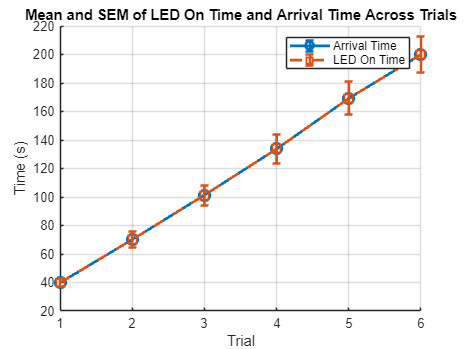


% Calculate means & SEM
mean_led = mean(led_on,1,'omitnan');
sem_led = std(led_on,0,1,'omitnan')/sqrt(nRats);
mean_arr = mean(arrival,1,'omitnan');
sem_arr = std(arrival,0,1,'omitnan')/sqrt(nRats);
mean_lat = mean(latency,1,'omitnan');
sem_lat = std(latency,0,1,'omitnan')/sqrt(nRats);

% Plot LED On Time (red dashed squares) and Arrival Time (blue solid circles)
figure;
hold on;
errorbar(1:nTrials, mean_arr, sem_arr, '-o', 'LineWidth', 2, 'Color', [0 0.4470 0.7410], ...
    'MarkerSize', 8, 'DisplayName', 'Arrival Time');
errorbar(1:nTrials, mean_led, sem_led, '--s', 'LineWidth', 2, 'Color', [0.8500 0.3250 0.0980], ...
    'MarkerSize', 8, 'DisplayName', 'LED On Time');
xlabel('Trial');
ylabel('Time (s)');
legend('show');
title('Mean and SEM of LED On Time and Arrival Time Across Trials');
grid on;
output_fig1 = strrep(filename, '.csv', '_6trial_plot.png');
saveas(gcf, output_fig1);
hold off;

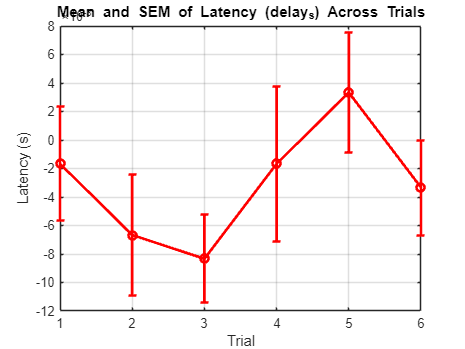


% Plot latency (delay_s) in red with circles
figure;
errorbar(1:nTrials, mean_lat, sem_lat, '-o', 'LineWidth', 2, 'Color', 'r');
xlabel('Trial');
ylabel('Latency (s)');
title('Mean and SEM of Latency (delay_s) Across Trials');
grid on;
output_fig2 = strrep(filename, '.csv', '_latency_6trial_plot.png');
saveas(gcf, output_fig2);